clear;

d = load('thruster_data.mat')

d = struct with fields:
             Ts: 0.0020
      data_sine: [15001x1x1 iddata]
    data_square: [15001x1x1 iddata]
         u_sine: [15001x1 double]
       u_square: [15001x1 double]
         y_sine: [15001x1 double]
       y_square: [15001x1 double]
           time: [15001x1 double]


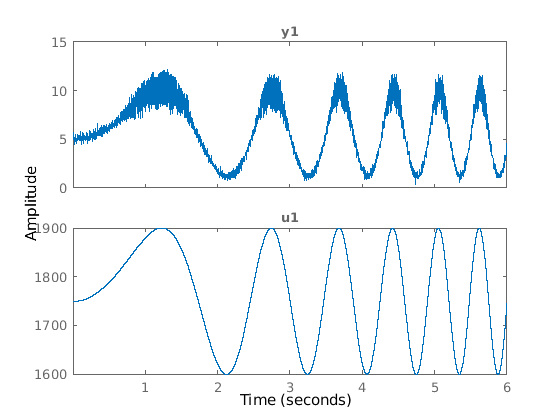


showSeconds = 6;
dataset = d.data_sine;
I = 1:(showSeconds / d.Ts);
shortData = iddata(dataset.y(I), dataset.u(I), d.Ts);
idplot(shortData);
title('');
saveFigure(gcf, 'figuresSoftlink/chirp-data-short');